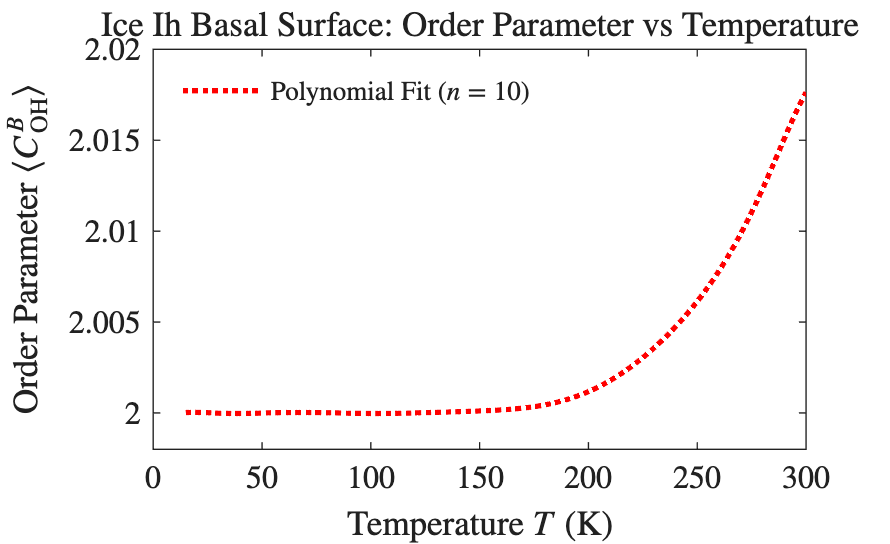

%% 10th-Degree Polynomial Fit for Ice Ih Basal Surface Order Parameter (Latest)
clear; clc; close all;

% 1. 定义温度区间 (10K 到 300K，取 1000 个点保证曲线平滑)
T = linspace(15, 300, 1000);

% 2. 提取最新的拟合系数 (严格从最高次 x^10 到常数项排列)
p = [-7.03542e-24, ... % x^10
      1.05067e-20, ... % x^9
     -6.70863e-18, ... % x^8
      2.39284e-15, ... % x^7
     -5.23049e-13, ... % x^6
      7.24117e-11, ... % x^5
     -6.34076e-09, ... % x^4
      3.40596e-07, ... % x^3
     -1.0498e-05,  ... % x^2
      0.000163069, ... % x^1
      1.99906];        % 常数项

% 3. 计算拟合曲线对应的序参量 C_OH
COH_fit = polyval(p, T);

% 4. 学术级绘图
figure('Color','white','Position',[100 100 850 520]);

plot(T, COH_fit, 'r:', 'LineWidth', 2.0, ...
    'DisplayName', 'Polynomial Fit ($n=10$)');

% 标题和坐标轴标签 (调用 LaTeX 解释器与 Times New Roman 字体)
title('Ice Ih Basal Surface: Order Parameter vs Temperature', ...
    'Interpreter', 'latex', 'FontSize', 14, 'FontName', 'Times New Roman');
xlabel('Temperature $T$ (K)', ...
    'Interpreter', 'latex', 'FontSize', 12, 'FontName', 'Times New Roman');
ylabel('Order Parameter $\langle C_{\mathrm{OH}}^B \rangle$', ...
    'Interpreter', 'latex', 'FontSize', 12, 'FontName', 'Times New Roman');

% 坐标轴全局格式化
set(gca, 'TickLabelInterpreter', 'latex', 'FontName', 'Times New Roman', ...
    'FontSize', 12, 'LineWidth', 1.0, 'Box', 'on');
grid off;

% 图例格式化 (精简尺寸，移除边框)
lgd = legend('Location', 'northwest', 'Interpreter', 'latex');
lgd.FontSize = 10;
legend('boxoff');

% 限制坐标轴范围以匹配物理实际
xlim([0 300]); 
ylim([1.998 2.02]);